%Calculo de inercias
%Inercia del brazo
Lb = 20/100 % longitud del brazo

Lb = 0.2000

dcm = 4.7/100 % distancia centro de masa

dcm = 0.0470

M = 12/1000 % masa del brazo

M = 0.0120

IB = ((1/12)*M*(Lb^2))+M*((dcm)^2)

IB = 6.6508e-05

%Inercia del motor
Mm = 3.5/1000 % Masa motor

Mm = 0.0035

am = 0.7/100 % Ancho motor

am = 0.0070

lm = 2.2/100 % longitud motor

lm = 0.0220

dm = 13.5/100 % distancia al motor

dm = 0.1350

Im = (1/12)*Mm*(3*(am^2)+(lm^2))+Mm*(dm)^2

Im = 6.3972e-05

%Inercia acople
aac = 0.75/100

aac = 0.0075

lac = 2/100 

lac = 0.0200

mac = 4.5/1000

mac = 0.0045

Iac = 1/2*mac*(aac^2)

Iac = 1.2656e-07

%Inercia total
IT = IB + Im + Iac

IT = 1.3061e-04


%Identificación
%Fuerza motor
g=9.8

g = 9.8000

dcp = 54/100

dcp = 0.5400

mcp = 0.009

mcp = 0.0090

C = g*(dcp*mcp-M*dcm-Mm*dm)

C = 0.0375

Fmo = -(-sind(AnguloMotor)*C)/dm

Fmo =     0.0290
    0.0290
    0.0290
    0.0290
    0.0290
    0.0290
    0.0290
    0.0338
    0.0338
    0.0338


p = polyfit(PWM,Fmo,1)

p =     0.0033    0.0203


a = p(1)

a = 0.0033

b = p(2)

b = 0.0203

yfit = polyval(p,PWM)

yfit =     0.0401
    0.0401
    0.0401
    0.0401
    0.0401
    0.0401
    0.0401
    0.0401
    0.0401
    0.0401


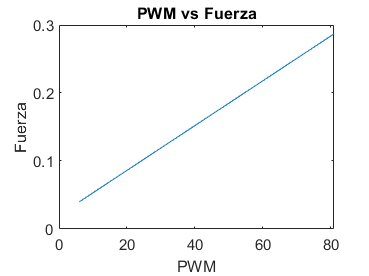

plot(PWM,yfit)
title("PWM vs Fuerza")
xlabel("PWM")
ylabel("Fuerza")

kmotor = a

kmotor = 0.0033

%Fricción
%[peaks,times] = findpeaks(angle,time)
f = fit(times,peaks,"exp1")

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       83.17  (77.5, 88.85)
       b =       -0.29  (-0.3209, -0.259)

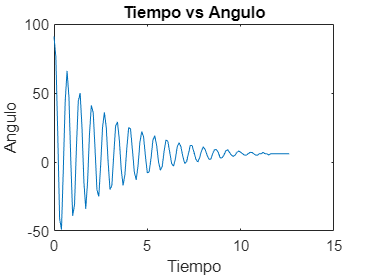

plot(time,angle)
title("Tiempo vs Angulo")
xlabel("Tiempo")
ylabel("Angulo")

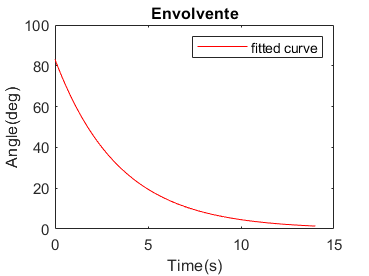

plot(f,"-r")
title("Envolvente")
xlabel("Time(s)")
ylabel("Angle(deg)")

gamma = 0.29

gamma = 0.2900

beta = gamma*2*IT

beta = 7.5752e-05


%Funcion de transferencia
num = [0 kmotor*dm/IT]

num =          0    3.4024


den = [1 beta/IT (g*(Mm*dm+M*dcm)/IT)*cosd(55)]

den =     1.0000    0.5800   44.6091


G = tf(num,den)

G =
 
         3.402
  --------------------
  s^2 + 0.58 s + 44.61
 
Continuous-time transfer function.



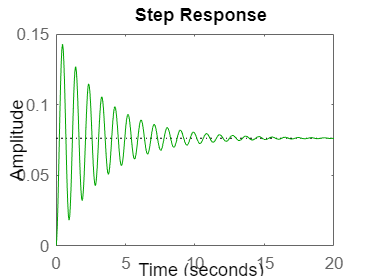

step(G,"-g")